# Numerical Analysis Take-Home Final, Fall 2019

## Maxwell Greene

## Problem #1

% Using Newton's Method for multivariate equations:
X = [1;1];Tol=.001;df=20;ak = 1.0;
funcs = @(x,y) [3*x^2-x*y^2+x^2*y-13; x*y-2*x^2+y^2-4];
while df > Tol
    Xn = X-ak*InvJac(X)*funcs(X(1),X(2));
    df =(dot((Xn-X),(Xn-X)))^0.5;
    X = Xn;
end
X'

ans =     2.3502    2.8780


## Problem #2

%Creating data
xVals = [0.90,0.95,0.77,0.79,0.25,0.55,0.09,0.85,0.24,0.06];
b = [4.71,4.87,4.42,4.46,3.88,4.06,3.93,4.60,3.88,3.95]';
A = [ones(10,1), xVals',xVals.^2'];
a = linsolve(A,b); a'

ans =     4.0043   -1.0028    2.0023


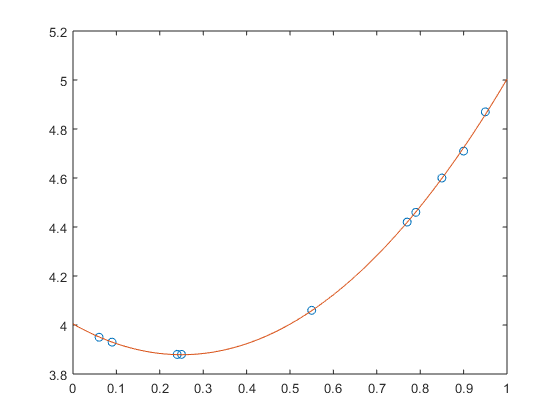

x = 0:.01:1;
plot(xVals,b,'o',x,a(1)+a(2)*x+a(3)*x.^2);

## Problem #5

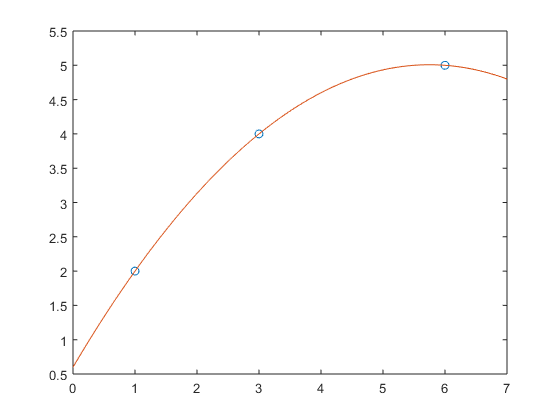

xVals = [1,3,6];
yVals = [2,4,5];
x = linspace(0,7,101);
y = ppval(spline(xVals,yVals),x);
plot(xVals,yVals,'o',x,y);

## Problem #11

%Load Data from Problem
tx = [0:.1111:1];
yx = [-0.0148;0.0714;0.0999;0.1099;0.1342;0.1399;0.1448;0.1417;0.1664;0.1679];

% Solving for optimum values of a and b in equation
% y''+ay'-y = t*exp(-bt), 0<=t<=1

% Optimization routine for values of a and b 
% least squares and odefunc.
optFunc = @(input) errorFunction(input(1),input(2),tx,yx);
optVals = optimize(optFunc,[0,0])

optVals =     8.2989    0.4248


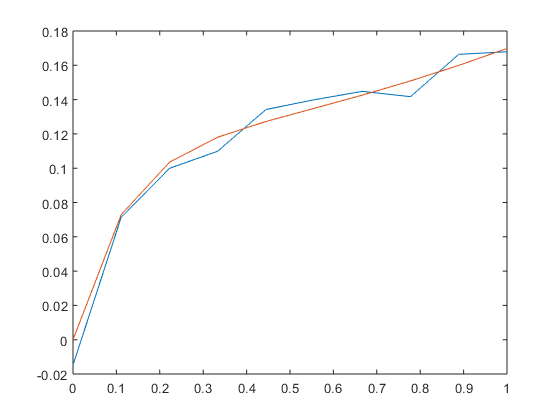


a = optVals(1); b = optVals(2);

[t,y] = ode23s(@(t,y) odefunc(t,y,a,b),tx,[0,1]);

plot(tx,yx,t,y(:,1));

## Functions used in questions:

Problem #1

function InvJ = InvJac(X)
    x = X(1); y = X(2);
    J = [6*x-y^2+2*x*y,-2*x*y+x^2;y-4*x,x+2*y];
    InvJ = inv(J);
end

Problem #11

function dydt = odefunc(t,z,c,d)
    dydt = [z(2);-c*z(2)+z(1)+t*exp(-d*t)];
end

function [a,b] = optimize(optfunc,params)
    [a,b] = fminsearch(optfunc,[params(1),params(2)]);
end

function error = errorFunction(a1,a2,tx,yx)
    [~,y] = ode23s(@(t,y) odefunc(t,y,a1,a2),tx,[0,1]);
    error = sum((y(:,1)-yx).^2);
end